# Example 3.11: Conditional Events in Gibbs Reactor

Note: this script reproduces Example 3.11 (Section 3.6) of **Statistics for Chemical Engineers**: joint, marginal, and conditional probabilities of two events of the Gibbs reactor. Victor Z UW-Madison, 2020 events for gibbs reactor example

clc; clear all; close all hidden;

## Data

create data set

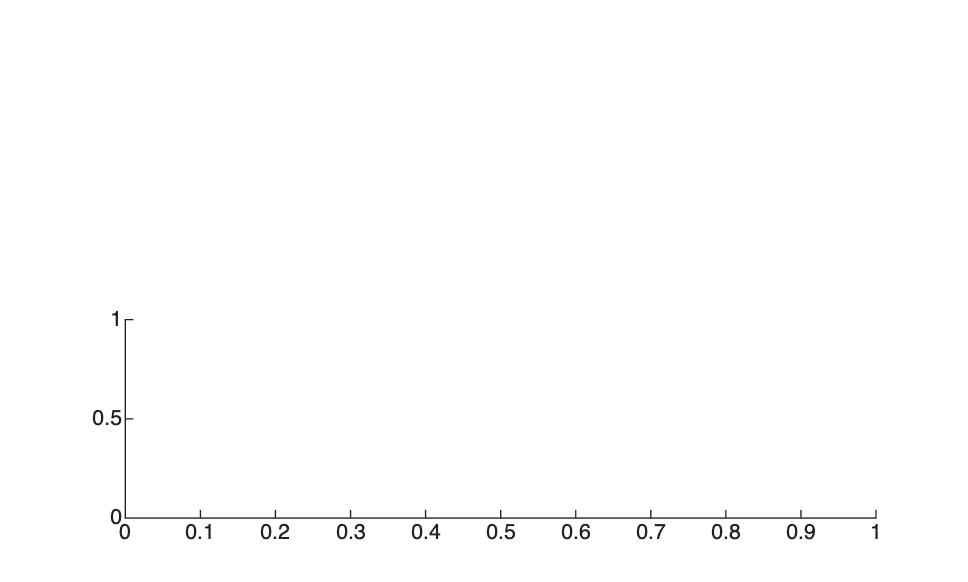

load ('./Data/gibbs_hightemp_class.dat')
datahigh=gibbs_hightemp_class;
data=[datahigh];
datan=data;
n=length(datan);

% corrupt data with noise to hide pattern 
rng(1); % For reproducibility 
P = datan(:,2)+randn(n,1); % pressure 
C = datan(:,3)+randn(n,1)*0.05; % conversion


figure(2)
subplot(2,2,[3,4])

## Events A, B, and A and B

draw domain for P [& P](http://=170)=120 and C in >= 0.5

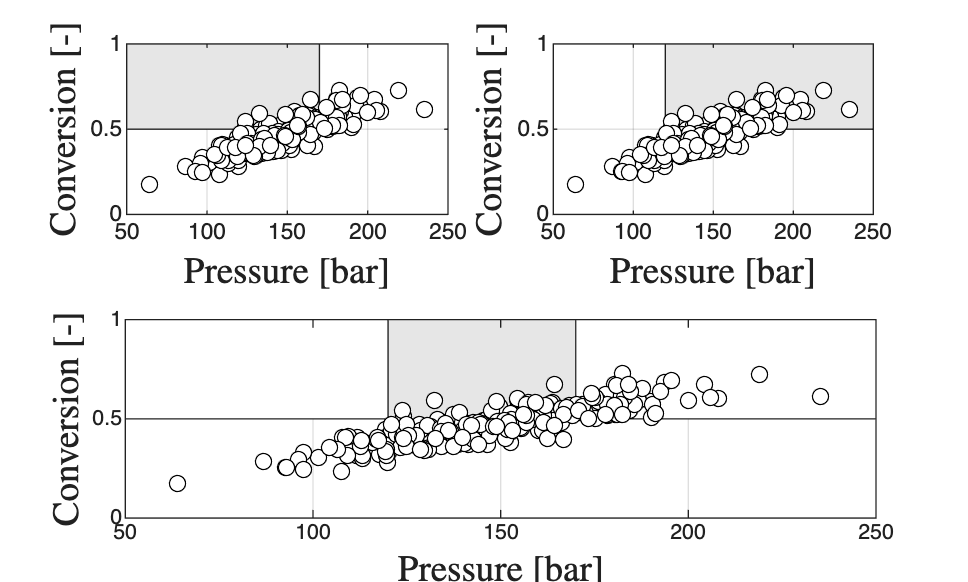

fill([50 170 170 50], [0.5 0.5 1 1], [1 1 1]);
hold on
fill([120 250 250 120], [0.5 0.5 1 1], [1 1 1]);
hold on
fill([120 170 170 120], [0.5 0.5 1 1], [0.9 0.9 0.9]);
hold on
scatter(P,C,'blacko','MarkerFaceColor','w')
grid on
xlabel('$\textrm{Pressure [bar]}$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Conversion [-]}$','Interpreter','latex','FontSize',14)
box on
hold on
axis([50 250 0 1])

figure(2)
subplot(2,2,1)
% draw domain for P <=170 && C in >= 0.5
fill([0 170 170 0], [0.5 0.5 1 1], [0.9 0.9 0.9]);
hold on
scatter(P,C,'blacko','MarkerFaceColor','w')
grid on
xlabel('$\textrm{Pressure [bar]}$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Conversion [-]}$','Interpreter','latex','FontSize',14)
box on
hold on
axis([50 250 0 1])

subplot(2,2,2)
% draw domain for  P>=120 and C in >= 0.5
fill([120 250 250 120], [0.5 0.5 1 1], [0.9 0.9 0.9]);
hold on
scatter(P,C,'blacko','MarkerFaceColor','w')
grid on
xlabel('$\textrm{Pressure [bar]}$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Conversion [-]}$','Interpreter','latex','FontSize',14)
box on
hold on
axis([50 250 0 1])
print -depsc ch3_gibbs_conditional.eps

## Joint, marginal, and conditional probabilities

get joint probability (A&B)

idx=0;
for i=1:n
    if P(i) <= 170 && P(i)>=120 && C(i)>=0.5
        idx=idx+1;
    end
end
probAandB = idx/n

probAandB = 0.1600


% get marginal probability (A)
idx=0;
for i=1:n
    if P(i)<=170 && C(i)>=0.5
        idx=idx+1;
    end
end
probA = idx/n

probA = 0.1600


% get marginal probability (B)
idx=0;
for i=1:n
    if P(i)>=120 && C(i)>=0.5
        idx=idx+1;
    end
end
probB = idx/n

probB = 0.3520


% get conditional (A|B)
probAB = probAandB/probB

probAB = 0.4545



% get conditional (B|A)
probBA = probAandB/probA

probBA = 1

## Note

As in the book, P(B | A) = 1: every point in A is also in B, so event A carries full information about event B.